# **Iterative methods tester**

In this livescript we test both Newton's and gradient method to find the numeric solution of the inverse kinematic problem

% Clear all the parameters from the workspace and also clear the command window.
clear all
clc

% Define initial conditions
q0 = [[0 0 0]',[pi/2 pi/2 pi/2]'];

% Define the step-sizes we are going to test.
alpha = [1/2 1/10];

% Desired position of the end effector
x_de = [2 1 0]';
% Matrices useful for the implementation of the algorithm
syms x y z
K = [cos(x)+cos(x+y)+cos(x+y+z),sin(x)+sin(x+y)+sin(x+y+z),x+y+z]';
J = jacobian([cos(x)+cos(x+y)+cos(x+y+z),sin(x)+sin(x+y)+sin(x+y+z),x+y+z],[x,y,z]);

### Gradient method simulations

% Parameter choice for the simulations
maxIter =2000;
errTh = 1e-6;

% Step-size a = 0.5
[gradient.q1, gradient.num_iter1, gradient.err1] = iterativeGradient(J, K, q0(:,1), x_de, alpha(1), maxIter, errTh);
[gradient.q2, gradient.num_iter2, gradient.err2] = iterativeGradient(J, K, q0(:,2), x_de, alpha(1), maxIter, errTh);
% Step-size a = 0.1
[gradient.q3, gradient.num_iter3, gradient.err3] = iterativeGradient(J, K, q0(:,1), x_de, alpha(2), maxIter, errTh);
[gradient.q4, gradient.num_iter4, gradient.err4] = iterativeGradient(J, K, q0(:,2), x_de, alpha(2), maxIter, errTh);

% For each solution print
% Final value of the solution as a fraction of pi

display(gradient.q1(:,gradient.num_iter1)/pi)

    0.2697
   -1.0942
    1.0006



display(gradient.q2(:,gradient.num_iter2)/pi)

    0.4058
    0.9864
   -0.7205



display(gradient.q3(:,gradient.num_iter3)/pi)

    0.0000
    0.5000
   -0.5000



display(gradient.q4(:,gradient.num_iter4)/pi)

    0.0000
    0.5000
   -0.5000




% Final value of the solution in degrees (positive angles)
display(mod(gradient.q1(:,gradient.num_iter1),2*pi)*180/pi)

   48.5471
  163.0515
  180.1089



display(mod(gradient.q2(:,gradient.num_iter2),2*pi)*180/pi)

   73.0464
  177.5465
  230.3028



display(mod(gradient.q3(:,gradient.num_iter3),2*pi)*180/pi)

    0.0037
   89.9957
  269.9986



display(mod(gradient.q4(:,gradient.num_iter4),2*pi)*180/pi)

    0.0037
   89.9957
  269.9986




% Stopping iteration
display(gradient.num_iter1)

        2000



display(gradient.num_iter2)

        2000



display(gradient.num_iter3)

   755



display(gradient.num_iter4)

   477




% Error at last iteration
display(gradient.err1(gradient.num_iter1+1))

    2.0592



display(gradient.err2(gradient.num_iter2+1))

    3.9121



display(gradient.err3(gradient.num_iter3+1))

   4.5952e-05



display(gradient.err4(gradient.num_iter4+1))

   4.5950e-05



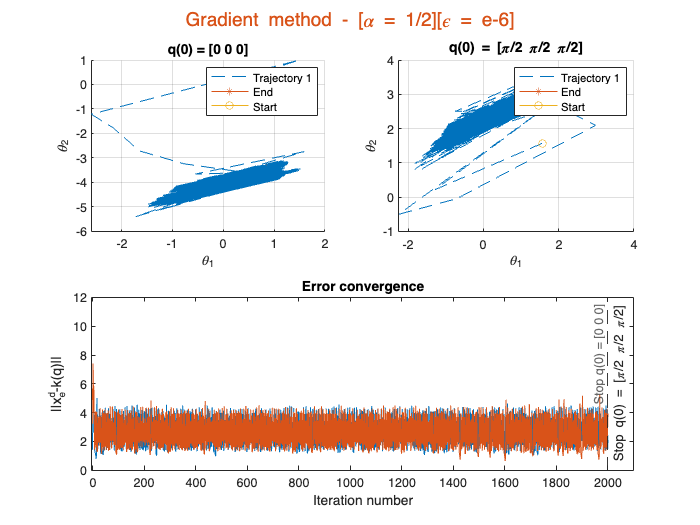

figure()
sgt = sgtitle('Gradient method - [\alpha = 1/2][\epsilon = e-6]');
sgt.FontSize = 15;
%sgt.FontWeight = 'bold';
sgt.Color = '#D95319';
sgt.Margin = 4;

subplot(2,2,1)
hold on
plot3(gradient.q1(1,:),gradient.q1(2,:),gradient.q1(3,:),'DisplayName','Trajectory 1 ','LineStyle','--')
plot3(gradient.q1(1,gradient.num_iter1),gradient.q1(2,gradient.num_iter1),gradient.q1(3,gradient.num_iter1),'Marker','*','DisplayName','End')
plot3(gradient.q1(1,1),gradient.q1(2,1),gradient.q1(3,1),'Marker','o','DisplayName','Start')
title('q(0) = [0 0 0]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,2)
hold on
plot3(gradient.q2(1,:),gradient.q2(2,:),gradient.q2(3,:),'DisplayName','Trajectory 1 ','LineStyle','--')
plot3(gradient.q2(1,gradient.num_iter2),gradient.q2(2,gradient.num_iter2),gradient.q2(3,gradient.num_iter2),'Marker','*','DisplayName','End')
plot3(gradient.q2(1,1),gradient.q2(2,1),gradient.q2(3,1),'Marker','o','DisplayName','Start')

title('q(0) = [\pi/2 \pi/2 \pi/2]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,[3,4])
plot(0:gradient.num_iter1, gradient.err1(1,1:(gradient.num_iter1+1)))
hold on
plot(0:gradient.num_iter2, gradient.err2(1,1:(gradient.num_iter2+1)))
xlabel('Iteration number')
ylabel('﻿||x_{e}^{d}-k(q)||')
xline(gradient.num_iter1,'--','Stop q(0) = [0 0 0]','LabelHorizontalAlignment','left');
xline(gradient.num_iter2,'--','Stop q(0) = [\pi/2 \pi/2 \pi/2]','LabelHorizontalAlignment','right');
xlim([-5 max(gradient.num_iter1,gradient.num_iter2)+100]);
ylim([0 12])
title('Error convergence')

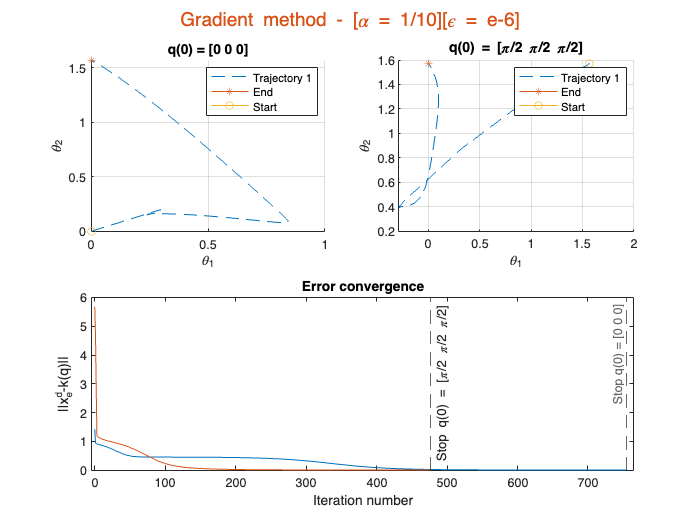

figure()
sgt = sgtitle('Gradient method - [\alpha = 1/10][\epsilon = e-6]');
sgt.FontSize = 15;
%sgt.FontWeight = 'bold';
sgt.Color = '#D95319';
sgt.Margin = 4;

subplot(2,2,1)
hold on
plot3(gradient.q3(1,:),gradient.q3(2,:),gradient.q3(3,:),'DisplayName','Trajectory 1 ','LineStyle','--')
plot3(gradient.q3(1,gradient.num_iter3),gradient.q3(2,gradient.num_iter3),gradient.q3(3,gradient.num_iter3),'Marker','*','DisplayName','End')
plot3(gradient.q3(1,1),gradient.q3(2,1),gradient.q1(3,1),'Marker','o','DisplayName','Start')
title('q(0) = [0 0 0]','FontSize',11)
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,2)
hold on
plot3(gradient.q4(1,:),gradient.q4(2,:),gradient.q4(3,:),'DisplayName','Trajectory 1 ','LineStyle','--')
plot3(gradient.q4(1,gradient.num_iter4),gradient.q4(2,gradient.num_iter4),gradient.q4(3,gradient.num_iter4),'Marker','*','DisplayName','End')
plot3(gradient.q4(1,1),gradient.q2(2,1),gradient.q4(3,1),'Marker','o','DisplayName','Start')

title('q(0) = [\pi/2 \pi/2 \pi/2]','FontSize',11)
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,[3,4])
plot(0:gradient.num_iter3, gradient.err3(1,1:(gradient.num_iter3+1)))
hold on
plot(0:gradient.num_iter4, gradient.err4(1,1:(gradient.num_iter4+1)))
xlabel('Iteration number')
ylabel('﻿||x_{e}^{d}-k(q)||')
xline(gradient.num_iter3,'--','Stop q(0) = [0 0 0]','LabelHorizontalAlignment','left');
xline(gradient.num_iter4,'--','Stop q(0) = [\pi/2 \pi/2 \pi/2]','LabelHorizontalAlignment','right');
xlim([-5 max(gradient.num_iter3,gradient.num_iter4)+10]);
title('Error convergence','FontSize',11)

maxIter = 50;
errTh = 1e-6;

Figure that takes into account the magnitude of the error of the netwon's methos 

[newton.q1, newton.num_iter1, newton.err1] = iterativeNewton(J, K, q0(:,1), x_de, maxIter, errTh);
[newton.q2, newton.num_iter2, newton.err2] = iterativeNewton(J, K, q0(:,2), x_de, maxIter, errTh);

% For each solution print
% Final value of the solution as a fraction of pi
display(newton.q1(:,newton.num_iter1)/pi)

    2.5000
   -4.5000
    2.0000



display(newton.q2(:,newton.num_iter2)/pi)

   -2.0000
    2.5000
   -0.5000



% Final value of the solution in degrees (positive angles)
display(mod(newton.q1(:,newton.num_iter1),2*pi)*180/pi)

   90.0000
  270.0000
    0.0000



display(mod(newton.q2(:,newton.num_iter2),2*pi)*180/pi)

    0.0000
   90.0000
  270.0000



% Stopping iteration
display(newton.num_iter1)

     7



display(newton.num_iter2)

     6



% Error at last iteration
display(newton.err1(newton.num_iter1+1))

     0



display(newton.err2(newton.num_iter2+1))

     0



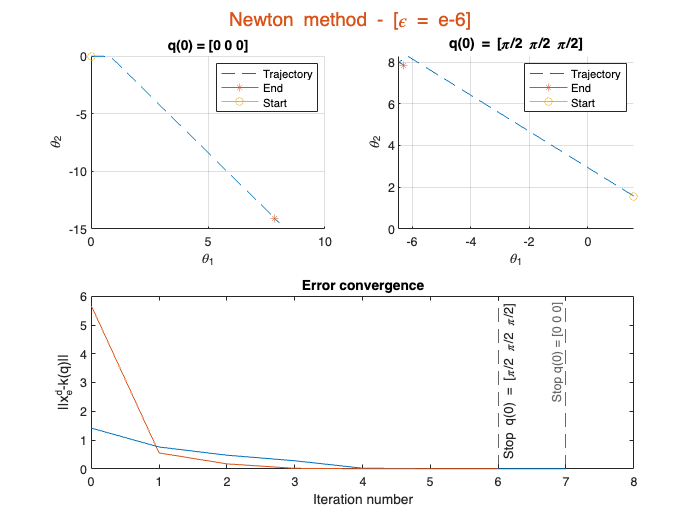

figure()
sgt = sgtitle('Newton method - [\epsilon = e-6]');
sgt.FontSize = 15;
%sgt.FontWeight = 'bold';
sgt.Color = '#D95319';
sgt.Margin = 4;

subplot(2,2,1)
hold on
plot3(newton.q1(1,:),newton.q1(2,:),newton.q1(3,:),'DisplayName','Trajectory','LineStyle','--')
plot3(newton.q1(1,newton.num_iter1),newton.q1(2,newton.num_iter1),newton.q1(3,newton.num_iter1),'Marker','*','DisplayName','End')
plot3(newton.q1(1,1),newton.q1(2,1),newton.q1(3,1),'Marker','o','DisplayName','Start')
title('q(0) = [0 0 0]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,2)
hold on
plot3(newton.q2(1,:),newton.q2(2,:),newton.q2(3,:),'DisplayName','Trajectory','LineStyle','--')
plot3(newton.q2(1,newton.num_iter2),newton.q2(2,newton.num_iter2),newton.q2(3,newton.num_iter2),'Marker','*','DisplayName','End')
plot3(newton.q2(1,1),newton.q2(2,1),newton.q2(3,1),'Marker','o','DisplayName','Start')

title('q(0) = [\pi/2 \pi/2 \pi/2]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,[3,4])
plot(0:newton.num_iter1, newton.err1(1,1:(newton.num_iter1+1)))
hold on
plot(0:newton.num_iter2, newton.err2(1,1:(newton.num_iter2+1)))
xlabel('Iteration number')
ylabel('﻿||x_{e}^{d}-k(q)||')
xline(newton.num_iter1,'--','Stop q(0) = [0 0 0]','LabelHorizontalAlignment','left');
xline(newton.num_iter2,'--','Stop q(0) = [\pi/2 \pi/2 \pi/2]','LabelHorizontalAlignment','right');
xlim([0 max(newton.num_iter1,newton.num_iter2)+1]);
title('Error convergence')

#### GRADIENT FUNCTION

function [q, nIter, err] = iterativeGradient(J, k, q0, x_de, stepSize, maxIter, errTh)
% --------------------  OUTPUT  --------------------
% q: vector of the solution evaluated at each step;
% nIter: number of the stopping interation;
% err: vector of the error evaluated at each step;

    % Initialization 
    syms x y z
    qTmp = zeros(3,maxIter);
    errTmp = zeros(1, maxIter+1);
    nIter = 0;

    % Evaluation of the error at first iteration (we consider error norm)
    qTmp(: , 1) = q0;    
    kTmp = subs(k,{x,y,z},qTmp(:,1)');
    errTmp(1) = norm(x_de-kTmp);
    
    j = 2;
    while (nIter < maxIter)
        nIter = j-1;
        % Jacobian at previus iteration
        Jtmp = subs(J,{x,y,z},qTmp(:,j-1)');
        % Solution update
        qTmp(:,j) = qTmp(:,j-1) + stepSize*(Jtmp)'*(x_de-kTmp);        
        % K(q) at current iteration
        kTmp = subs(k,{x,y,z},qTmp(:,j)');
        % K(q) at current iteration
        errTmp(j) = norm(x_de-kTmp);

        % Early stopping strategy based on error's improvement
        if abs(errTmp(j)-errTmp(j-1)) < errTh
            break  
        end
        j = j+1;
    end

    % Output made only of nonzero elements
    q = qTmp(:,1:nIter+1);
    err = errTmp(1:nIter+1);
end

### NEWTON'S FUNCTION

function [q, nIter, err] = iterativeNewton(J, k, q0, x_de, maxIter, errTh)
% --------------------  OUTPUT  --------------------
% q: vector of the solution evaluated at each step;
% nIter: number of the stopping interation;
% err: vector of the error evaluated at each step; 

    % Initialization    
    syms x y z
    qTmp = zeros(3,maxIter);
    errTmp = zeros(1, maxIter);
    nIter = 0;

    % Evaluation of the error at first iteration (we consider error norm)
    qTmp(: , 1) = q0;    
    kTmp = subs(k,{x,y,z},qTmp(:,1)');
    errTmp(1) = norm(x_de-kTmp);

    j = 2;
    while (nIter < maxIter)
        nIter = j-1;
        % Jacobian at previus iteration
        Jtmp = subs(J,{x,y,z},qTmp(:,j-1)');
        % Evaluation of the pseudo-inverse - this handles the
        % non-invertible case
        Jinv=pinv(Jtmp);
        % Solution update
        qTmp(:,j) = qTmp(:,j-1) + Jinv*(x_de-kTmp);
        % K(q) at current iteration
        kTmp = subs(k,{x,y,z},qTmp(:,j)');
        % K(q) at current iteration
        errTmp(j) = norm(x_de-kTmp);

        % Early stopping strategy based on error's improvement
        if abs(errTmp(j)-errTmp(j-1)) < errTh
            break  
        end
        j = j+1;
    end
    % Considering as output only nonzero elements
    q = qTmp(:,1:nIter+1); 
    err = errTmp(1:nIter+1);
end